# **Generación de Variables Aleatorias (VAs) y Convergencia de Sumas de VAs**

lambda = 1.5;   % Tasa
n =      1000;   % Número de variables aleatorias
r =      10000;   % Número de realizaciones

- **Generación de la PDF**

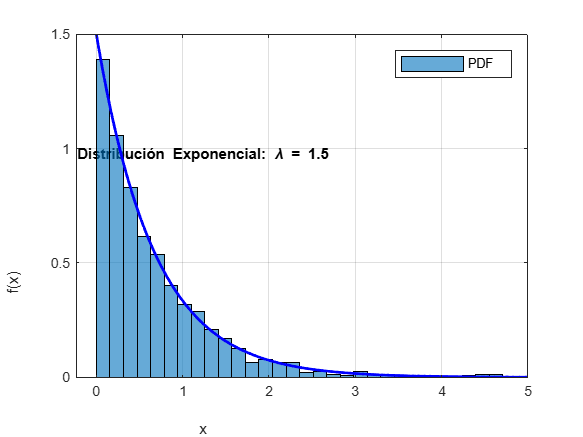

% Media y desviación estándar
mu = 1/lambda;
sigma = 1/lambda;

% Dominio X
x = 0:0.01:5;

% Muestras exponencial
muestras = exprnd(mu, 1, n);

% Histograma
figure;
histogram(muestras, 30, 'Normalization', 'pdf');
hold on;

% PDF exponencial
pdf = lambda * exp(-lambda * x);

% Gráfica
plot(x, pdf, 'b', 'LineWidth', 2);
grid on;
xlabel('x');
ylabel('f(x)');
title(['Distribución Exponencial: \lambda = ', num2str(lambda)]);
legend('PDF');
hold off;

- **Consideración de *****n***** variables iid y *****r***** realizaciones**

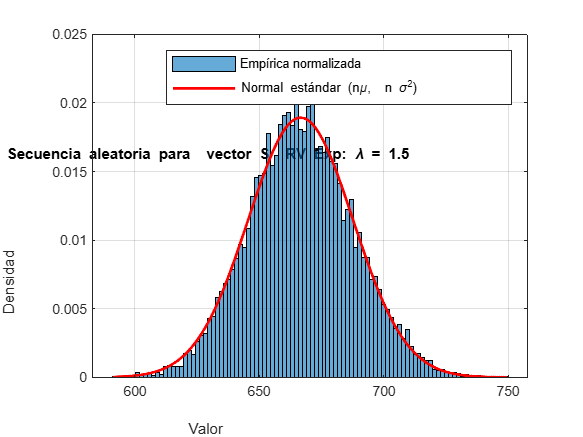

% Variables aleatorias exponenciales IID X_i
X = exprnd(1/lambda, n, r); %dimension n x r 

% Secuencia aleatoria S=sum(X_i)
S = sum(X, 1);
size(S)

% Histograma
figure;
histogram(S, 100, 'Normalization', 'pdf');
hold on

% PDF Normal esperada 
x = linspace(min(S), max(S), 1000);
plot(x, normpdf(x, n*mu, sqrt(n)*sigma), 'r', 'LineWidth', 2);

xlabel('Valor ');
ylabel('Densidad');
title(['Secuencia aleatoria para  vector S  RV Exp: \lambda = ',num2str(lambda)]);
legend('Empírica normalizada', 'Normal estándar (n\mu,  n \sigma^2)', 'Interpreter', 'tex');  % Omitiendo el parámetro, ya que 'tex' es el valor por defecto

grid on;
hold off;

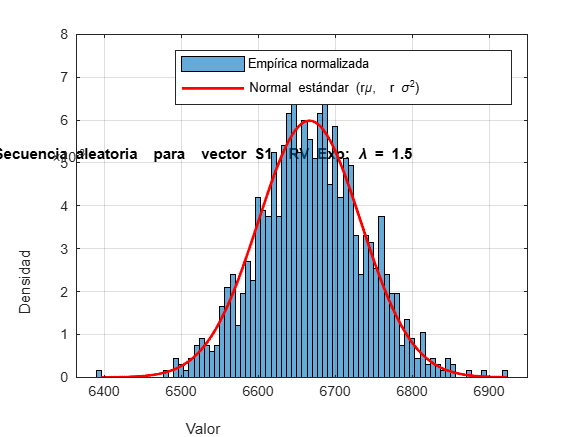

% Vector de n sumas
S1 = sum(X,2);
size(S1)

% Histograma
figure;
histogram(S1, 80, 'Normalization', 'pdf');
hold on

% PDF Normal esperada
x = linspace(min(S1), max(S1), 1000);
plot(x, normpdf(x, r*mu, sqrt(r)*sigma), 'r', 'LineWidth', 2);

xlabel('Valor');
ylabel('Densidad');
title(['Secuencia aleatoria  para  vector S1  RV Exp: \lambda = ', num2str(lambda)]);
legend('Empírica normalizada', 'Normal estándar (r\mu,  r \sigma^2)', 'Interpreter', 'tex');  % Omitiendo el parámetro, ya que 'tex' es el valor por defecto

grid on;